Show case AUC


%the_file=fullfile(working_dir, subject_dir, file_name);

%the_file="D:\work\Najafi\000016\sub-mouse1-fni16_ses-161220141515.nwb";



nwbfile = nwbRead(the_file)

nwbfile =   NwbFile with properties:

                                nwb_version: '2.2.2'
                           file_create_date: [1×1 types.untyped.DataStub]
            general_source_script_file_name: []
                                 identifier: '151001_001_ch2-PnevPanResults-161220-141515'
                        session_description: '151001_001_ch2-PnevPanResults-161220-141515'
                         session_start_time: 2015-10-01T00:00:00.000000-04:00
                  timestamps_reference_time: 2015-10-01T00:00:00.000000-04:00
                                acquisition: [0×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: []
                            general_devices: [1×1 types.untyped.Set]
             general_experiment_description: []
             

%doesnt work

nwbfile.processing.get('Trial-based-Segmentation').nwbdatainterface

Error using indexing
The specified key is not present in this container.

Error in types.untyped.Set/get (line 165)
                o{i} = obj.map(name{i});


trial_seg_module = nwbfile.processing.get('Ophys').nwbdatainterface

trial_seg_module =   9×1 Set array with properties:

          ImageSegmentation: [types.core.ImageSegmentation]
        dFoF_commitIncorrAl: [types.core.DfOverF]
        dFoF_firstSideTryAl: [types.core.DfOverF]
    dFoF_firstSideTryAl_COM: [types.core.DfOverF]
              dFoF_goToneAl: [types.core.DfOverF]
            dFoF_initToneAl: [types.core.DfOverF]
              dFoF_rewardAl: [types.core.DfOverF]
         dFoF_stimAl_allTrs: [types.core.DfOverF]
     dFoF_stimAl_noEarlyDec: [types.core.DfOverF]


trial_seg_module.get('dFoF_initToneAl').roiresponseseries.get('Trial_15')

ans =   RoiResponseSeries with properties:

                   rois: [1×1 types.untyped.SoftLink]
     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
                   data: [484×45 types.untyped.DataPipe]
              data_unit: 'au'
     starting_time_rate: 0.0324
               comments: 'no comments'
                control: []
    control_description: []
        data_conversion: 1
        data_resolution: -1
            description: '(ROIs x time), aligned to event_id: 16'
          starting_time: -0.4854
             timestamps: []



dfof=trial_seg_module.get('dFoF_initToneAl').roiresponseseries.get('Trial_15').data.load;
size(dfof)

ans =    484    45


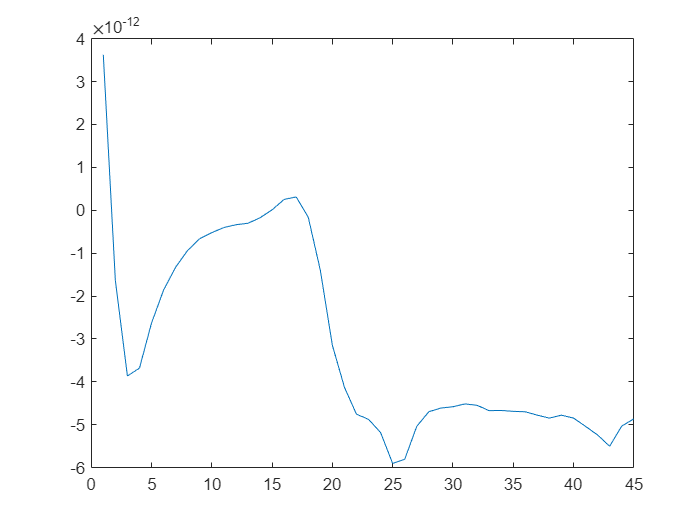

% example in the notebook:
   % exc_correct_lr = out{1}(:, :, correct_low_rate_trial);
   % exc_correct_lr = exc_correct_lr(is_exc, :, :);
plot(dfof(12,:)) 

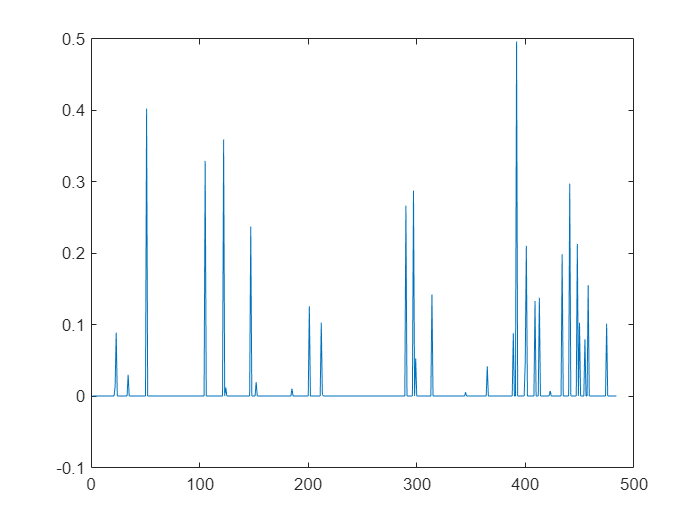

plot(dfof(:,10)) 

Problem: the structure should have been (ROI , time_series,  trial) but instead it is in the form of (timeseries[:#ROI], ROI[#45 ]) 

% Visualizing the ROI-table
roi_tcourse = trial_seg_module.get('dFoF_initToneAl').roiresponseseries.get('Trial_00'); 
good_roi_mask = roi_tcourse.rois.deref(nwbfile).data.load; % good_roi_mask here refers a 1D array of ROI indices, indexing into the ROI-table
roi_table = roi_tcourse.rois.deref(nwbfile).table.refresh(nwbfile);  % table is returned as ObjectView, do refresh() to recreate the actual object





roi_table_df = table();
colnames = roi_table.vectordata.keys();
for k = 1 : numel(colnames)
    if ~strcmp(colnames{k}, 'image_mask')
        d = roi_table.vectordata.get(colnames{k}).data;
        if isa(d, 'types.untyped.DataStub')
            roi_table_df.(colnames{k}) = d.load;
        elseif isa(d, 'cell')
            roi_table_df = [roi_table_df, cell2table(d, 'VariableNames', {colnames{k}})];
        end
    end
end
display(roi_table_df)

roi_table_df = 683×6 table
    fitness    neuron_type    offsets_ch1_pix    roi2surr_sig    roi_id    roi_status
    _______    ___________    _______________    ____________    ______    __________

     -Inf      inhibitory          29052              1             0         good   
     -Inf      excitatory           5111              0            93         good   
     -Inf      excitatory           5802              0            92         good   
     -Inf      excitatory           3131              0            91         good   
     -Inf      excitatory           3833              0            90         good   
     -Inf      excitatory          11859              0            89         good   
     -Inf      excitatory           4708              0            86         go

trial_set = nwbfile.intervals.get('trials');

Error using indexing
The specified key is not present in this container.

Error in types.untyped.Set/get (line 165)
                o{i} = obj.map(name{i});



b_set=nwbfile.intervals_trials.vectordata

b_set =   10×1 Set array with properties:

        first_commit: [types.hdmf_common.VectorData]
             go_tone: [types.hdmf_common.VectorData]
           init_tone: [types.hdmf_common.VectorData]
       second_commit: [types.hdmf_common.VectorData]
         stim_offset: [types.hdmf_common.VectorData]
          stim_onset: [types.hdmf_common.VectorData]
       trial_is_good: [types.hdmf_common.VectorData]
    trial_pulse_rate: [types.hdmf_common.VectorData]
      trial_response: [types.hdmf_common.VectorData]
          trial_type: [types.hdmf_common.VectorData]



behavioral_df = table();
colnames = b_set.keys();

for k = 1 : numel(colnames)
    d = b_set.get(colnames{k}).data;
    behavioral_df.(colnames{k}) = d.load;
end

Dot indexing is not supported for variables of this type.


neuron_type = roi_table.vectordata.get('neuron_type').data(good_roi_mask + 1);  % +1 to account for python 0-based indexing
% Display neuron_type for ease of visualization
disp(neuron_type(1:45))

is_inh = strcmp(neuron_type, 'inhibitory');
is_exc = strcmp(neuron_type, 'excitatory')



Helpers

function output = get_trialsegmented_roi_timeseries(event_name, pre_stim_dur, post_stim_dur, trial_seg_module)
    event_roi_timeseries = trial_seg_module.get(event_name).roiresponseseries;
    tvec = event_roi_timeseries.get('Trial_00').timestamps.load;  % timestamps from all trial are the same, so get one from trial_0
    % check if pre/post stim duration is out of bound
    pre_stim_dur = max(tvec(1), pre_stim_dur);
    post_stim_dur = min(tvec(end), post_stim_dur); 
    % extract data
    ix = (tvec >= pre_stim_dur) & (tvec <= post_stim_dur);
    out = [];
    trials = event_roi_timeseries.keys;
    for tr = 1: numel(trials)
        d = event_roi_timeseries.get(trials(tr)).data.load';  % tranpose the extract the data into (roi x time)
        out(:, :, end+1) = d(:, ix);
    end
    out(:, :, 1) = [];
    output = {out, tvec(ix)};
end   